# MATLAB and ROS 1

Setup IPs for connecting the Virtual Linux Machine and MATLAB on the laptop

matlabIP = '192.168.48.1'; % IP address of MATLAB host PC (in a command prompt, 
% do a "ipconfig" and note the Vnet1 address)
rosIP = '192.168.127.130';    % IP address of ROS enabled machine
% (in a Terminal window, do a "ifconfig")

setenv('ROS_IP',matlabIP); 
setenv('ROS_MASTER_URI',['http://' rosIP ':11311']); 

rosinit(rosIP,11311)

The value of the ROS_IP environment variable, 192.168.48.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_25931 with NodeURI http://192.168.48.1:49774/ and MasterURI http://192.168.127.130:11311.


## Image acquisition

rostopic list

/camera/camera_info                                                   
/camera/image_raw                                                     
/camera/image_raw/compressed                                          
/camera/image_raw/compressed/parameter_descriptions                   
/camera/image_raw/compressed/parameter_updates                        
/camera/image_raw/compressedDepth                                     
/camera/image_raw/compressedDepth/parameter_descriptions              
/camera/image_raw/compressedDepth/parameter_updates                   
/camera/image_raw/theora                                              
/camera/image_raw/theora/parameter_descriptions                       
/camera/image_raw/theora/parameter_updates                            
/camera/parameter_descriptions                                        
/camera/parameter_updates                                             
/clock                                                                
/cmd_v

rostopic info /right_camera/image_raw

Type: sensor_msgs/Image
 
Publishers:
* /gazebo (http://192.168.127.130:36389/)
 
Subscribers:


sub = rossubscriber('/right_camera/image_raw','DataFormat','struct');
[msg2,status,statustext] = receive(sub,10)

msg2 = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1×1 struct]
         Height: 480
          Width: 640
       Encoding: 'rgb8'
    IsBigendian: 0
           Step: 1920
           Data: [921600×1 uint8]


status = logical
   1


statustext = 'success'

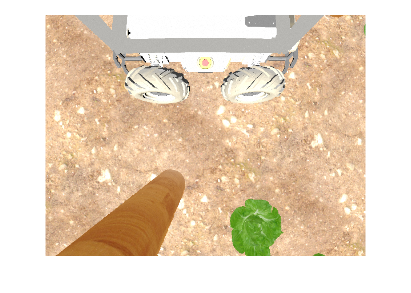

imageFormatted = rosReadImage(msg2);
imshow(imageFormatted)

## Image processing

Use of the Color Threshoder MATLAB Apps. Try all color spaces. You will get better results with L*a*b space. It consists of a luminosity 'L*' or brightness layer, chromaticity layer 'a*' indicating where color falls along the red-green axis, and chromaticity layer 'b*' indicating where the color falls along the blue-yellow axis. 

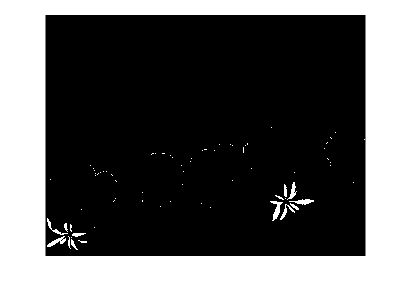

load im1.mat
colorThresholder(imageFormatted)
[BW,maskedRGBImage] = mycreateMask(imageFormatted);
imshow(BW)

## Move Straight

  % Create a publisher which can "talk" to Robot and tell it to move
  pub = rospublisher('/cmd_vel', 'geometry_msgs/Twist');

  % Create a Twist message and add linear x and angular z values
  move_cmd = rosmessage(pub);

  % Set publish rate at 10 Hz
  rate = rosrate(10);

  disp("Moving Straight");

Moving Straight


  move_cmd.Linear.X =0.3;           % move in X axis at 0.3 m/s
  move_cmd.Angular.Z = 0.0;

  % For the next 3 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(3)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end

## Rotating Counterclockwise

  disp("Rotating");

Rotating


  move_cmd.Linear.X = 0.0;
  move_cmd.Angular.Z = 0.2;         % rotate at 0.2 rad/sec

  % For the next 3 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(3)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end

## Stop

  disp("Stopping");
  move_cmd.Linear.X = 0.0;
  move_cmd.Angular.Z = 0.0;         % Giving both zero will stop the robot

  % For the next 1 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(1)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end
  disp("Exit");

## Shutdown ROS node

 rosshutdown;

Shutting down global node /matlab_global_node_37263 with NodeURI http://192.168.48.1:59972/ and MasterURI http://192.168.127.130:11311.
